%скрипт для извлечения Q суммарной по ГРС для запаса
clear
d = dir('C:\Users\user\MATLAB Drive\1Exponenta\27.02_zapas\data_all\Запас данные');
d(1:3) = [];
t = [];

for i = 1:numel(d) 
    disp(i) % демо считывания данных по месяцам
    str = d(i).folder +"\"+ d(i).name; % считываем имя файла в директории d
    a = readfile_all(str); % читаем файл, к которому обращаемся
    t = [t;a]; % считываем каждый файл и конкатенируем с предыдущим
    % t - содержит все ненормированные данные по 12 месяцев по 4 ГРС
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10



% t(:,1:end-1) = [];% удаляем все кроме последней колонки, там сумма по ГРС

save data_zapas_q_out t

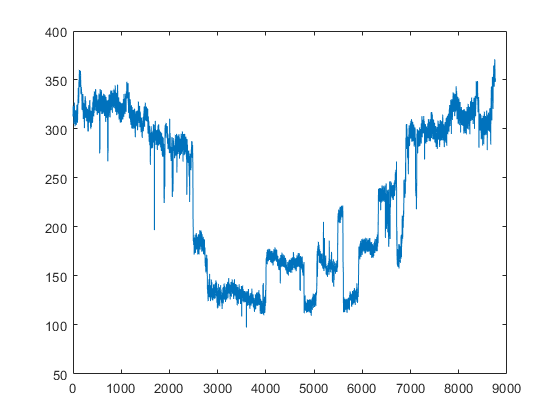

plot(t);

function t = readfile_all(str)
[t,txt] = xlsread(str,'КС, МГ');
%%
s = all(isnan(t));
t(:,s) = [];
b = all(isnan(t),2);
t(b,:) = [];
end